# Homework 5

**Problem 0. **Download the .mat file 

file = load('Homework5.mat');

**Problem 1. **The `score1` variable contains scores received by 100 students on some test. The `pass1` variable contains 0s or 1s indicating whether each student ended up passing the course. Visualize these data using a scatter plot. Now suppose we want to use logistic regression to predict whether a student passes the course based on his/her score. Our model is *f(score) = 1/(1+exp(-(a*score+b))* where *a* and *b* are free parameters. Suppose *a* is 1 and *b* is –72. Plot this model on the scatter plot using a red line. Then calculate the likelihood of the data points under this model and report this to the command window. Now suppose *a* is 0.5 and *b* is –32. Plot this model on the scatter plot using a blue line, and report the likelihood of the data points under this model to the command window. Which of the two models results in the higher likelihood? For the model with the higher likelihood, what is the percentage of data points correctly classified?

score1 = file.score1;
pass1 = file.pass1;

figure; hold on;
scatter(score1, pass1, 'bo')
xlabel('Score');
ylabel('Passed?');
ax = axis;
axis([ax(1:2) -.2 1.2]);

% Set the evaluation values to the x-axis limits
ax = axis;
x = linspace(ax(1),ax(2),100);

% Define the model function
modelfun = @(xx, params) 1./(1+exp(-(xx*params(1) + params(2))));

% Esimate parameters for the model
par = [1 -72; 0.5 -32];

%Initialize variables
colors = ['r' 'b'];
likelihood = zeros(length(par),1);
names={'Params: 1; -72'; 'Params: 0.5; -32'};

for i = 1:length(par)
    
    plots(i) = plot(x, modelfun(x, par(i,:)), colors(i));
    
    modelfit = modelfun(score1, par(i,:));
    % Calculate the likelihoods
    likelihood0 = prod(1-modelfit(pass1==0));
    likelihood1 = prod(modelfit(pass1==1));
    likelihood(i) = likelihood0 * likelihood1;
    
    modelfit = (modelfit >= 0.5);
    correct = sum(modelfit==pass1)/length(pass1) * 100;
    
    fprintf('Likelihood for case %d is %.g.\n',i,likelihood(i));
end

Likelihood for case 1 is 3e-11.


Likelihood for case 2 is 2e-44.


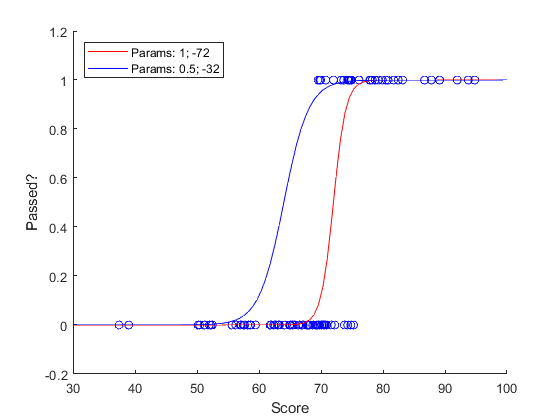


legend(plots, names, 'Location', 'northwest');


[mx,ix] = max(likelihood);
fprintf('Case %d has the higher likelihood. (%.g)\n',ix, mx);

Case 1 has the higher likelihood. (3e-11)


fprintf('%.1f percent correct. \n',correct(ix));

64.0 percent correct. 


hold off;

**Problem 2. **The `classA` and `classB` variables each contain measurements of 1,000 subjects on three different dimensions. How well can we classify whether a subject belongs to class A or class B based on measurement of the three dimensions? To answer this question, use linear discriminant analysis (LDA) to perform classification, and specifically, use leave-one-out cross-validation to obtain unbiased estimates of classification accuracy. For what percentage of subjects does LDA successfully predict class assignment?

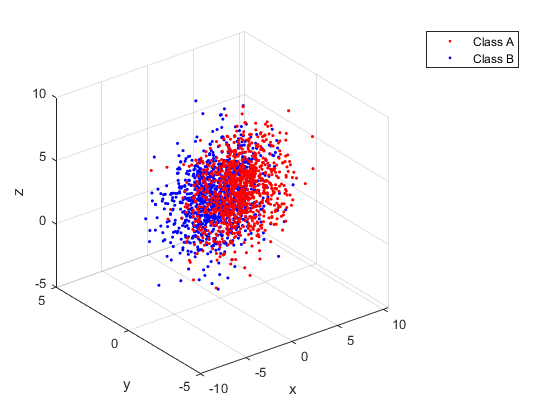

classA = file.classA;
classB = file.classB;

% Visualize data
figure; hold on; view(3); grid;
scatter3(classA(:,1), classA(:,2), classA(:,3), 'r.');
scatter3(classB(:,1), classB(:,2), classB(:,3), 'b.');
xlabel('x');
ylabel('y');
zlabel('z');
legend(['Class A'; 'Class B']);


nA = size(classA,1);
nB = size(classB,1);

X = [classA; classB;];

y = [zeros(nA,1); ones(nB,1)];
 
pred = zeros(nA+nB,1);

% Leave-one-out cross-validation
for p=1:length(y)
    
    % Estimate indices for testing and training sets
    trainix = setdiff(1:length(y),p);
    testix = p;
    
    % Save classified
    pred(testix) = classify(X(testix,:), X(trainix, :), y(trainix), 'linear');
end

% Calculate the percentage of correct attempts
pctcorrect = sum(pred == y) / length(y) * 100;
fprintf('Correctly predicted %.1f%% of items. \n', pctcorrect);
